%Prob1_1
alpha=1+mod(840,3);
t=0:0.001:1/alpha;
f1= alpha*cos(2*pi*5*alpha*t);
f2= alpha*0.5*cos(2*pi*6*alpha*t);
f3= alpha*0.25*cos(2*pi*10*alpha*t);
plot(t,f1,'r')
legend('Amplitude 1 and Frequency 5Hz','Amplitude 0.5 and Frequency 6Hz','Amplitude 0.25 and Frequency 10Hz')

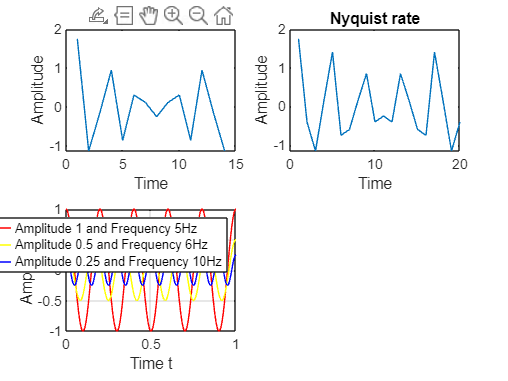

hold on
plot(t,f2,'y')
hold on
plot(t,f3,'b')
hold off
ylabel("Amplitude")
xlabel("Time t")
grid on

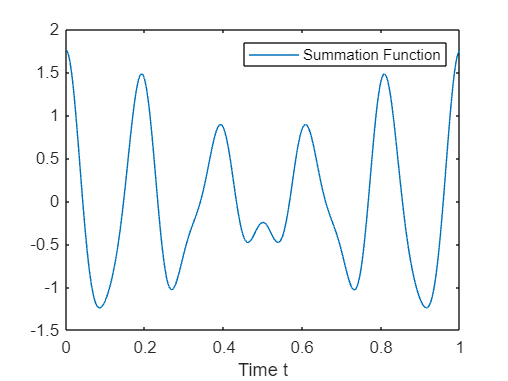

%prob1_2
f=f1+f2+f3;
plot(t,f)
legend("Summation Function")
xlabel("Time t")

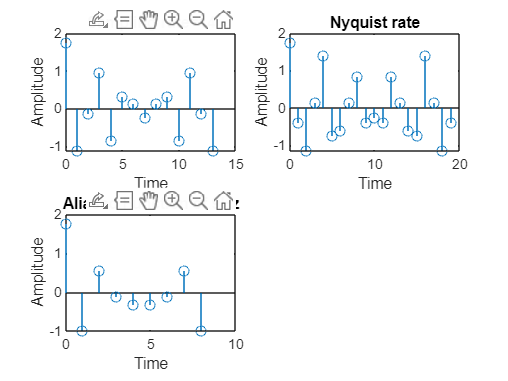

%prob1_3
Fs1=14*alpha;
Fs2=2*10*alpha;
t1=0:1/Fs1:(1/alpha-1/Fs1);
t2=0:1/Fs2:(1/alpha-1/Fs2);
f1= alpha*cos(2*pi*5*alpha*t1);
f2= alpha*0.5*cos(2*pi*6*alpha*t1);
f3= alpha*0.25*cos(2*pi*10*alpha*t1);
F1=f1+f2+f3;
subplot(2,2,1)
stem(0:Fs1-1,F1);
xlabel('Time');
ylabel('Amplitude');
title('Sampling rate=14');
%For Nyquist rate

f1= alpha*cos(2*pi*5*alpha*t2);
f2= alpha*0.5*cos(2*pi*6*alpha*t2);
f3= alpha*0.25*cos(2*pi*10*alpha*t2);
F2=f1+f2+f3;
subplot(2,2,2)
stem(0:Fs2-1,F2);
xlabel('Time');
ylabel('Amplitude');
title('Nyquist rate');

%For aliasing 6Hz with 3Hz
Fs3=9;
t3=0:1/Fs3:(1/alpha-1/Fs3);
f1= alpha*cos(2*pi*5*alpha*t3);
f2= alpha*0.5*cos(2*pi*6*alpha*t3);
f3= alpha*0.25*cos(2*pi*10*alpha*t3);
F3=f1+f2+f3;
subplot(2,2,3)
stem(0:Fs3-1,F3);
title('Aliased Function of 9Hz')
xlabel('Time');
ylabel('Amplitude');

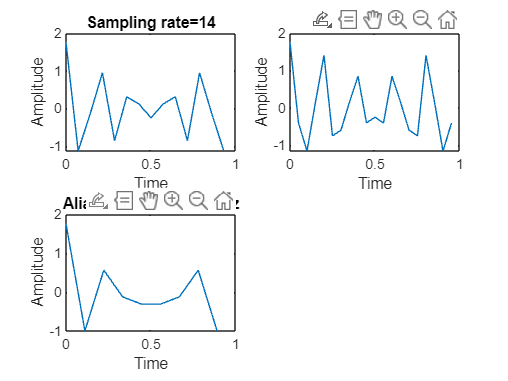

%Prob1_4
Fs1=14*alpha;
Fs2=2*10*alpha;
t1=0:1/Fs1:(1/alpha-1/Fs1);
t2=0:1/Fs2:(1/alpha-1/Fs2);
f1= alpha*cos(2*pi*5*alpha*t1);
f2= alpha*0.5*cos(2*pi*6*alpha*t1);
f3= alpha*0.25*cos(2*pi*10*alpha*t1);
f=f1+f2+f3;
subplot(2,2,1)
plot(t1,f);
xlabel('Time');
ylabel('Amplitude');
title('Sampling rate=14');
%For Nyquist rate

f1= alpha*cos(2*pi*5*alpha*t2);
f2= alpha*0.5*cos(2*pi*6*alpha*t2);
f3= alpha*0.25*cos(2*pi*10*alpha*t2);
f=f1+f2+f3;
subplot(2,2,2)
plot(t2,f);
xlabel('Time');
ylabel('Amplitude');
title('Nyquist rate');

%For aliasing 6Hz with 3Hz
Fs3=9;
t3=0:1/Fs3:(1/alpha-1/Fs3);
f1= alpha*cos(2*pi*5*alpha*t3);
f2= alpha*0.5*cos(2*pi*6*alpha*t3);
f3= alpha*0.25*cos(2*pi*10*alpha*t3);
F3=f1+f2+f3;
subplot(2,2,3)
plot(t3,F3);
title('Aliased Function of 9Hz')
xlabel('Time');
ylabel('Amplitude');

y =          0
    0.0373
    0.0745
    0.1116
    0.1485
    0.1853
    0.2218
    0.2580
    0.2938
    0.3292


Fs = 11025

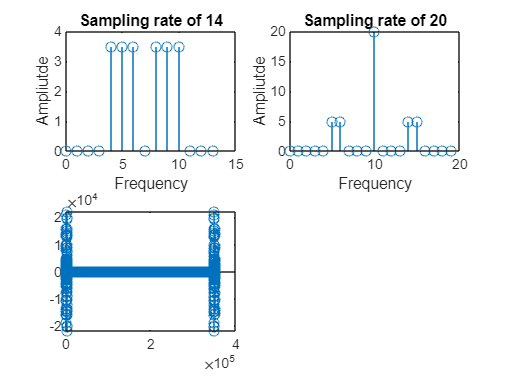

%prob_2
frequencies=[261.63,293.66,329.63,349.23,392.00,440.00,493.88,523.25];
sample_rate=44100;
fs=1/sample_rate;
duration=1;
sequence=[];
for freq=frequencies
    t=0:(1/sample_rate):duration;
    signal=sin(2*pi*freq*t);
    sequence=[sequence,signal];
end

sequence= sequence/max(abs(sequence));
filename='audio2.wav';
audiowrite(filename,sequence,sample_rate/4);
[y,Fs]=audioread("audio2.wav")

sound(y,Fs)
% sound(sequence,sample_rate/2);

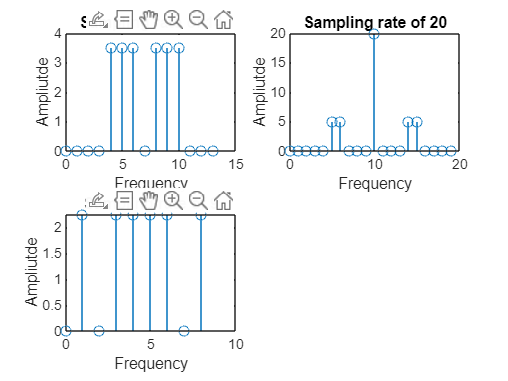

%Prob1_5
fs1=14;
n1=0:fs1-1;
t1=1/fs1;
fft_1=fft(cos(2*pi*5*n1*t1)+cos(2*pi*6*n1*t1)+cos(2*pi*10*n1*t1));
N1=length(n1);
fk1=(0:N1-1)*fs1/N1;
subplot(2,2,1)
stem(fk1,(abs(fft_1).^2)/N1)
xlabel("Frequency")
ylabel("Ampliutde")
title("Sampling rate of 14")
fs2=20;
n2=0:fs2-1;
t2=1/fs2;
fft_2=fft(cos(2*pi*5*n2.*t2)+cos(2*pi*6*n2.*t2)+cos(2*pi*10*n2.*t2));
N2=length(n2);
fk2=(0:N2-1)*fs2/N2;
subplot(2,2,2)
stem(fk2,(abs(fft_2).^2)/N2)
xlabel("Frequency")
ylabel("Ampliutde")
title("Sampling rate of 20")
fs3=9;
n3=0:fs3-1;
t3=1/fs3;
fft_3=fft(cos(2*pi*5*n3.*t3)+cos(2*pi*6*n3.*t3)+cos(2*pi*10*n3.*t3));
N3=length(n3);
fk3=(0:N3-1)*fs3/N3;
subplot(2,2,3)
stem(fk3,(abs(fft_3).^2)/N3)
xlabel("Frequency")
ylabel("Ampliutde")
title("Sampling rate of 9")

filename = 'Track001.wav';
[y, original_fs] = audioread(filename);
downsampling_factors = [2, 3, 4];

for i = 1:length(downsampling_factors)
    factor = downsampling_factors(i);
    
    downsampled_signal = downsample(y, factor);
    new_fs = original_fs / factor;
    
    
    output_filename = sprintf('downsample.wav', factor);
    audiowrite(output_filename, downsampled_signal, new_fs);
    
    
    sound(downsampled_signal, new_fs);
    pause(length(downsampled_signal) / new_fs + 0.5); % Pause to hear the audio
end


upsampling_factor = 2;


upsampled_signal = ifft(fft(y) .* [ones(1, upsampling_factor), zeros(1, length(y) * (upsampling_factor - 1))]);


upsampled_signal = upsampled_signal / max(abs(upsampled_signal)) * max(abs(y));


output_filename = sprintf('upsampled.wav', upsampling_factor);
audiowrite(output_filename, upsampled_signal, original_fs);


sound(upsampled_signal, original_fs)

y1 =     0.1351
    0.1451
    0.1632
    0.1778
    0.1753
    0.2122
    0.2366
    0.2798
    0.3230
    0.2892
